clc
clear
close all

defines

load s20/data120.mat
s = tf('s');

Posunutie dat na 0 0

indx = 50;
t = t(indx:end) - t(indx);
y = y(indx:end) - y(indx);
figure(1)
hold on
plot(t,y)

Prva metoda

ind1 = 50;
ind2 = 300;

t1 = t(ind1);
t2 = t(ind2);
y1 = y(ind1);
y2 = y(ind2);

K = y(end);
T = (t2-t1)/log((K-y1)/(K-y2));
x =(log((K-y1)/K))/(log((K-y2)/K));
D = (t2*x-t1)/(x-1);

F = K/(1+T*s)*exp(-D*s);
t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);
plot(t_model,y_model)

druha metoda

ind1 = find_t(y,0.7); 
ind2 = find_t(y,0.33);

t1 = t(ind1);
t2 = t(ind2);

K = y(end);
T = 1.245*(t1-t2);
D = 1.498*t2-0.498*t1;

F = K/(1+T*s)*exp(-D*s);
t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);
plot(t_model,y_model)

tretia metoda

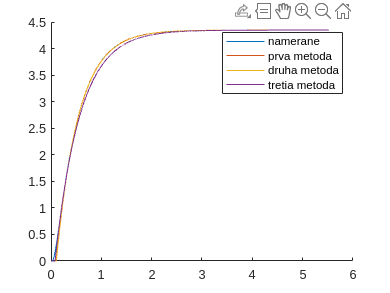

ind1 = find_t(y,0.4); 
ind2 = find_t(y,0.28);
t1 = t(ind1);
t2 = t(ind2);

K = y(end);
T = 5.5*(t1-t2);
D = 2.8*t2-1.8*t1;

if(D >= 0)
    F = K/(1+T*s)*exp(-D*s);
else
    F = K/(1+T*s);
end
t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);
plot(t_model,y_model)
legend("namerane","prva metoda","druha metoda","tretia metoda")